# Curvas de comportamiento de COVID 19

El comportamiendo de epidemias puede ser simulado con modelos matematicos o modelos estadisticos. En este estudio nos concentraremos en los modelos matematicos. Especificamente usaremos un modelo **compartimental**. Los modelos de este tipo simplifican el problema al dividir la poblacion total en compartimentos, asumiendo que cada individuo en un mismo compartimento tiene las mismas características.

## Requisitos

Para simular el comportamiento de la epidemia usaremos el modelo **SIR **(**S**usceptible **I**nfectious **R**emoved). El modelo consiste de tres compartimiendos

- **S**: Personas susceptibles. Estos se pueden pasar al grupo de **I**nfectados al tener contacto con uno de ellos.

- **I**: Personas infectadas. Aquellos que son portadores de la enfermedad.

- **R**: Personas con inmunidad o que murieron. Este grupo puede ser interpretado de varias formas, pero son aquellas que fueron infectadas y ya no pertenecen a ese grupo.

Usaremos el modelo y modificaremos las variables necesarias para asimilar diferentes cepas de covid, asi como diferentes tamaños de población y la densidad de estas.

Al final compararemos nuestras gráficas de variables continuas contra las variables discretas y veremos que similitudes y diferencias se creán entre la realidad y este modelo matematico simple.

## Creación del modelo

Usaremos el modelo **SIR** de acuerdo al siguiente sistema de ecuaciones:


$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \mathrm{I}+\delta \cdot \mathrm{R}\\
\frac{\textrm{dI}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \mathrm{I}-\gamma \cdot \mathrm{I}\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\delta \cdot \mathrm{R}
\end{array}$$


Aqui $\beta \cdot \mathrm{S}\cdot \mathrm{I}$ representa la cantidad de personas que es contagiada, es decir, los que pasan de ser susceptibles a ser contagiados (infectados). Es por esto que la constante $\beta$ (beta) representa la taza de infección. Se sabe que unas cepas de covid son más infeccionsas que otras.

De la misma forma $\delta$ representa la perdida de inmunidad. Por eso $\delta \cdot \mathrm{R}$ representa a aquellos que pasan del compartimiento de removed, a ser susceptibles otra vez, es decir que pueden volverse a infectar.

Por último $\gamma$(gamma) representa la taza de recuperación.

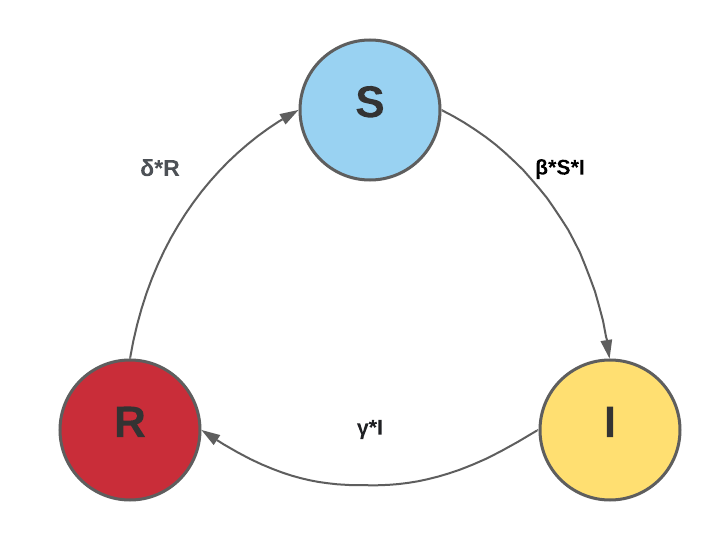

    **Figura 1: **Diagrama de flujo del modelo SIR

### Modelo SIRD

Podemos agregar más variantes al modelo base **SIR **para hacerlo más interesante y realista. En este caso agregamos un compartimiento extra para los decesos. De está forma, solo pasarán a **R** los recuperados y los muertos se pasaran al nuevo compartimento **D**

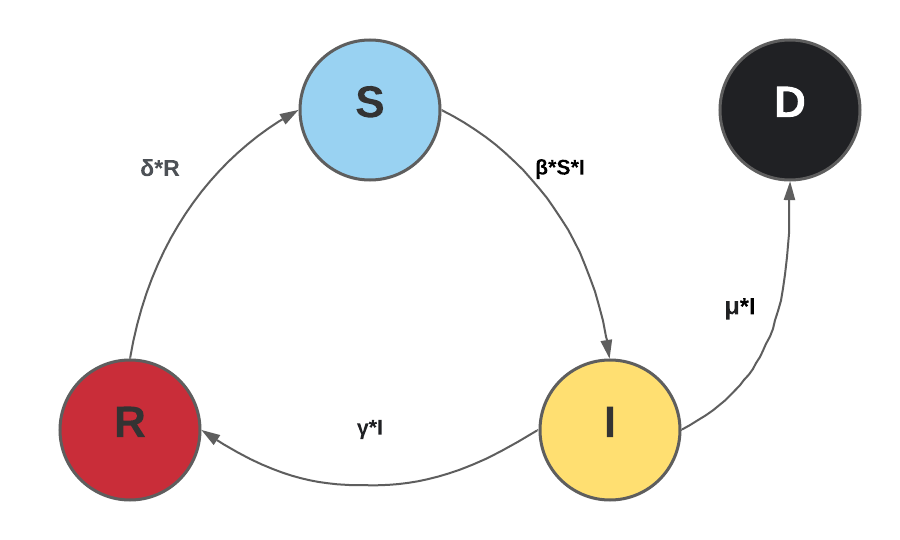

**    Figura 2: **Diagrama de flujo del modelo SIRD 

Nuestro nuevo sistema de ecuaciones se ve de la siguiente manera.


$$\begin{array}{l}
\frac{\textrm{dS}}{\textrm{dt}}=-\beta \cdot \mathrm{S}\cdot \mathrm{I}+\delta \cdot \mathrm{R}\\
\frac{\textrm{dI}}{\textrm{dt}}=\beta \cdot \mathrm{S}\cdot \mathrm{I}-\gamma \cdot \mathrm{I}-\mu \cdot I\\
\frac{\textrm{dR}}{\textrm{dt}}=\gamma \cdot \mathrm{I}-\delta \cdot \mathrm{R}\\
\frac{\textrm{dD}}{\textrm{dt}}=\mu \cdot I
\end{array}$$


## Implementación

Antes de implementar el modelo es importante mencionar las razones por las que el modelo no verá como una curva real de covid con varios repuntes. Los coeficientes usados aqui son promedios obtenidos de los datos de [owid](https://covid.ourworldindata.org/data/owid-covid-data.csv) para el reino Unido (UK). Esto causa que no se tome en cuenta las diferentes medidas tomadas por el gobierno para controlar en cierto espacio de tiempo. solo refleja como se comporta en promedio.

Para la taza de perdida de immunidad no existen los datos para calcularlo en para un país en especifico. así que usaremos un valor promedio usado en [otros estudios](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7598795/).

% Model parameters for the UK
beta = 9.6905E-09; % rate of infection
%no mask
%beta = beta*1.1;

gamma = 0.532271959; % rate of recovery 
delta = 1/60; % rate of immunity loss 100 days
mu = 0.085470461; % fatallity rate
N = 66650000 % Total UK population N = S + I + R

N = 66650000

I0 = 10; % initial number of infected
T =  500; % period of 300 days
dt = 1/4; % time interval of 6 hours (1/4 of a day)
fprintf('Value of parameter R0 is %.2f',N*beta/gamma)

Value of parameter R0 is 1.21

[t,S,I,R,D] = modelSIRD(beta,gamma,delta,mu,N,I0,T,dt);
% Plots that display the epidemic outbreak
% Curve
%plot(t,S); 



% beta = 5*10^-9; % rate of infection
% gamma = 0.12; % rate of recovery (try also 0.07)
% 
% N = 6*10^7; % Total population N = S + I + R
% I0 = 10; % initial number of infected
% T = 300; % period of 300 days
% dt = 1/4; % time interval of 6 hours (1/4 of a day)
% delta = 1/60;
% [t,S,I,R] = modelSIR(beta,gamma,delta,N,I0,T,dt);
% plot(t,[S,I,R])
% hold on
% %plot(t,I); 
% %plot(t,R); 
% %plot(t,D); 
% 
% grid on;
% xlabel('Days'); 
% ylabel('Number of individuals');
% legend('S','I','R');
% hold off

## Pruebas y resultados

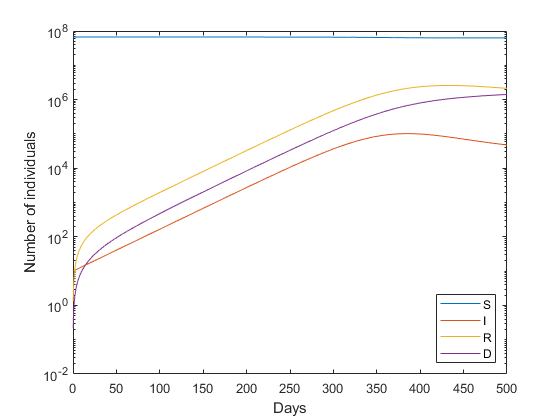

semilogy(t,[S,I,R,D])
hold on
%plot(t,I); 
%plot(t,R); 
%plot(t,D); 


%grid on;
xlabel('Days'); 
ylabel('Number of individuals');
legend('S','I','R','D','Location','southeast');
hold off


[v,i]=max(I);
d=i/4;
fprintf('el pico de casos activos es de %d y sucede %d dias después de que empezó la pandemia',round(v),round(d))

el pico de casos activos es de 101819 y sucede 386 dias después de que empezó la pandemia

[v,i]=max(D);
d=i/4;
fprintf('el total de muertes son %d al día %d desde que empezó la pandemia',round(v),round(d))

el total de muertes son 1412387 al día 500 desde que empezó la pandemia

La gráfica que resulta del modelo SIRD puede no distanciar mucho de la real por las limitaciones que mencionamos antes. Es importante ver que el modelo solo nos muestra el rol que juega cada variable dentro de una determinada población. En el caso del Reino unido, la tasa de mortalidad varia desde 2% hasta 14% dependiendo de la fecha.

## Comparación datos reales

Comparemos la acumulación de muertes de nuestra predicción contra la realidad https://coronavirus.data.gov.uk/details/download

[~,~,data] = xlsread('UK-cum-death.csv');
data

data = 514×5 cell array
    {'areaCode' }    {'areaName'      }    {'areaType'}    {'date'     }    {'cumDailyNsoDeathsByDeathDate'}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/25/2021'}    {[                      153926]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/24/2021'}    {[                      153916]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/23/2021'}    {[                      153897]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/22/2021'}    {[                      153891]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/21/2021'}    {[                      153876]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/20/2021'}    {[                      153864]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/19/2021'}    {[                      153848]}
    {'K02000001'}    {'United Kingdom'}    {'overview'}    {'6/18/2021'}    {[                      1538

column1 = data(end-499:end,5); %500 dias
deaths = cell2mat(column1)

deaths =       153753
      153742
      153729
      153714
      153698
      153683
      153677
      153664
      153658
      153646


days = 500:-1:1

days =    500   499   498   497   496   495   494   493   492   491   490   489   488   487   486   485   484   483   482   481   480   479   478   477   476   475   474   473   472   471   470   469   468   467   466   465   464   463   462   461   460   459   458   457   456   455   454   453   452   451


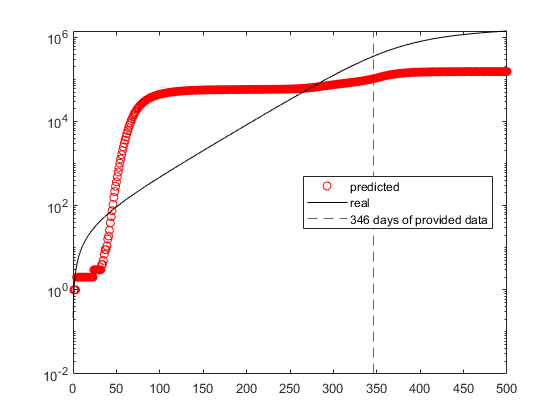

semilogy(days,deaths,"r o")
hold on
semilogy(t,D,"k")
xline(346,"--");
legend("predicted","real","346 days of provided data","Location","best")
hold off

Se puede ver como este modelo sigue una especie de promedio, pero no tiene en cuenta los picos (rebrotes) de covid debido a la relajacion de medidas sanitarias para prevenirlo. Un modelo más realista se puede visualizar con un [diagrama ](https://pubs.acs.org/doi/10.1021/acs.iecr.0c04754)como el siguiente.

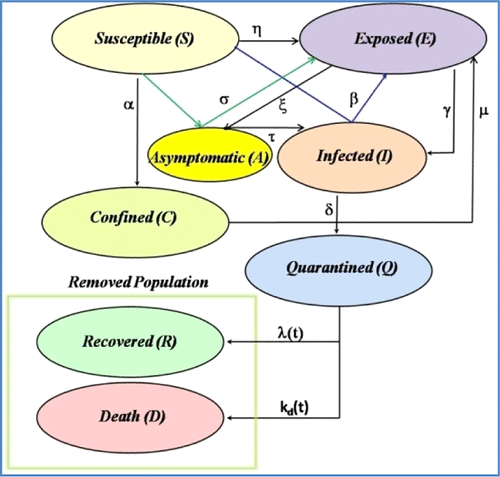

    **Figura 3: **Diagrama SIRD avanzado

Los datos tomados para este estudio son los promedios de esas variables desde que empezó el 1 de febrero de 2020 hasta el pico de casos el 9 de enero de 2021. Para estas ultimas fechas el proceso de vacunación (que empezo en diciembre 13 de 2020) juega un papel importante en reducir el número de decesos y contagios.

Veamos ahora que pasa si se relajan las medidas preventivas, es decir un aumento en el coeficiente de infección **beta**

betaBase = beta

betaBase = 9.6905e-09

beta = 1.0660e-08

Value of parameter R (Reproduction rate) is 1.33

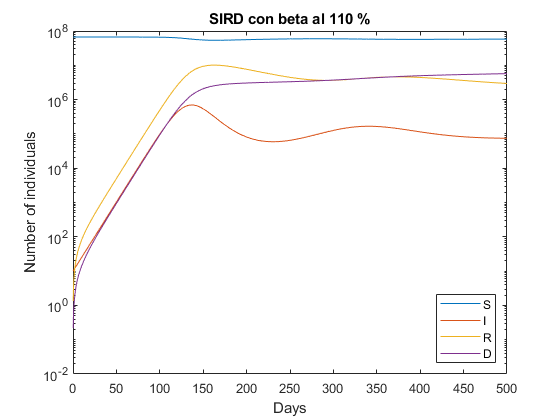

el total de muertes son 5716279 al día 500 desde que empezó la pandemia 


beta = 1.1629e-08

Value of parameter R (Reproduction rate) is 1.46

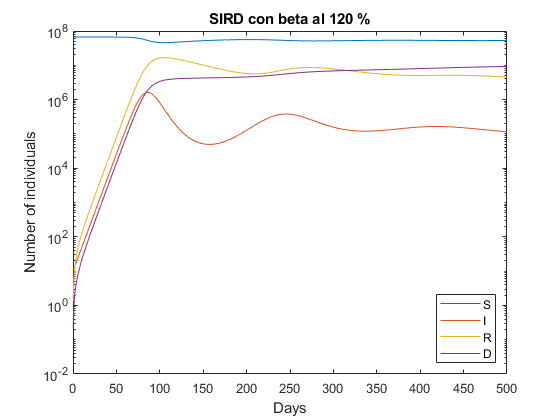

el total de muertes son 9269041 al día 500 desde que empezó la pandemia 


beta = 1.2598e-08

Value of parameter R (Reproduction rate) is 1.58

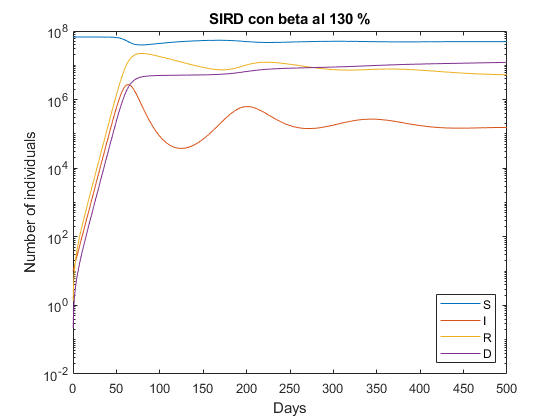

el total de muertes son 12173548 al día 500 desde que empezó la pandemia 


beta = 1.3567e-08

Value of parameter R (Reproduction rate) is 1.70

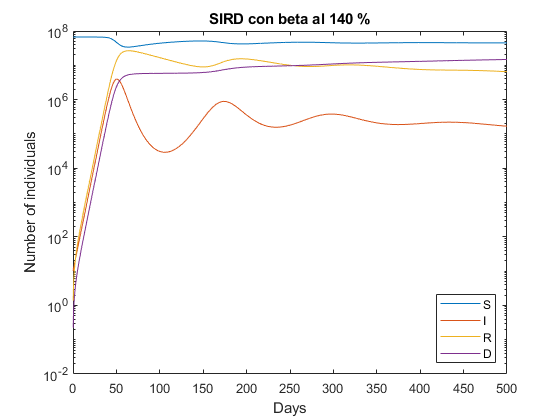

el total de muertes son 14777172 al día 500 desde que empezó la pandemia 


beta = 1.4536e-08

Value of parameter R (Reproduction rate) is 1.82

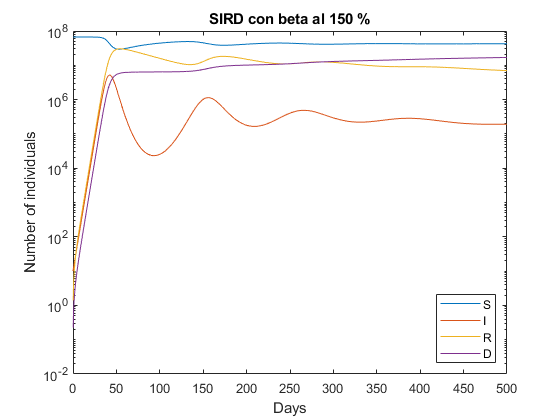

el total de muertes son 16935175 al día 500 desde que empezó la pandemia 


for i = 1.1:0.1:1.5
    figure;
    beta = betaBase * i
    fprintf('Value of parameter R (Reproduction rate) is %.2f',N*beta/gamma)
    [t,S,I,R,D] = modelSIRD(beta,gamma,delta,mu,N,I0,T,dt);
    semilogy(t,[S,I,R,D])    
    
    hold on
    title("SIRD con beta al "+i*100+" %")
    xlabel('Days'); 
    ylabel('Number of individuals');
    legend('S','I','R','D','Location','southeast');
    hold off
    [v,i]=max(D);
    d=i/4;
    fprintf('el total de muertes son %d al día %d desde que empezó la pandemia \n',round(v),round(d))
end

Podemos ver como un incremento de apenas el 10% resulta en un gran incremento de decesos. Que en un escenario real, incrementaria a la vez la tasa de mortalidad y decrementaria por lo tanto la tasa de recuperación. Esto debido al sobrecupo de los hospitales.

## Conclusión

% x

## Funciones

function [t,S,I,R] = modelSIR(beta,gamma,delta,N,I0,T,dt)
    [t,y] = runKut4(@(t,y) SIRfunc(t,y,beta,gamma,delta),0,dt,T,[N-I0;I0;0]);    
    S=y(:,1);
    I=y(:,2);
    R=y(:,3);
end

function [t,S,I,R,D] = modelSIRD(beta,gamma,delta,mu,N,I0,T,dt)
    [t,y] = runKut4(@(t,y) SIRDfunc(t,y,beta,gamma,delta,mu,N),0,dt,T,[N-I0;I0;0;0]);  
    S=y(:,1);
    I=y(:,2);
    R=y(:,3);
    D=y(:,4);
end

function [xSol,ySol] = runKut4(F,x0,h,xStop,y0)
    % 4th-order Runge--Kutta integration.
    % USAGE: [xSol,ySol] = runKut4(dEqs,x,y,xStop,h)
    % INPUT:
    % dEqs = handle of function that specifies the    
    % 1st-order differential equations
    % F(x,y) = [dy1/dx dy2/dx dy3/dx ...].
    % x,y = initial values; y must be row vector.
    % xStop = terminal value of x.
    % h = increment of x used in integration.
    % OUTPUT:
    % xSol = x-values at which solution is computed.
    % ySol = values of y corresponding to the x-values.
    reshape( y0, [],1 ); % column vector
    xSol = zeros(2,1); 
    ySol = zeros(length(y0),2);
    xSol(1) = x0; 
    ySol(:,1) = y0;
    i = 1;
    x=x0;
    y=y0;    
    while x < xStop
        i = i + 1;
        h = min(h,xStop - x);
        K1 = h*F(x,y);
        K2 = h*F(x + h/2,y + K1/2);
        K3 = h*F(x + h/2,y + K2/2);
        K4 = h*F(x+h,y + K3);
        y = y + (K1 + 2*K2 + 2*K3 + K4)/6;
        x = x + h;
        xSol(i) = x;
        ySol(:,i) = y; 
    end
    
    xSol = xSol';
    ySol=ySol';
end

function dydt = SIRfunc(t,y,beta,gamma,delta)
    dydt = zeros(3,1);
    %dydt(1)=dS
    %dydt(2)=dI
    %dydt(3)=dR
    dydt(1) = (-beta.*y(2).*y(1) + delta.*y(3));    
    dydt(2) = (beta.*y(2).*y(1) - gamma.*y(2));
    dydt(3) = (gamma.*y(2) - delta.*y(3));
end

function dydt = SIRDfunc(t,y,beta,gamma,delta,mu,N)
    dydt = zeros(4,1);
    %dydt(1)=dS
    %dydt(2)=dI
    %dydt(3)=dR
    dydt(1) = (-beta.*y(2).*y(1) + delta.*y(3));
    dydt(2) = (beta.*y(2).*y(1) - gamma.*y(2) -mu.*y(2));
    dydt(3) = (gamma.*y(2) - delta.*y(3));
    dydt(4) = mu.*y(2);
end

